close all;
clear all;

s = tf('s');

%proces
K = 1.187;
tau = 0.186;
u = 6;

Gp = tf([K],[tau 1])

Gp =
 
     1.187
  -----------
  0.186 s + 1
 
Continuous-time transfer function.
Model Properties




%pid
P = 0.8;
I = 5;
D = 0.001;
N = 10;

Gr = P+ I/s + (D * N) / (1 + N/s)

Gr =
 
  0.81 s^2 + 13 s + 50
  --------------------
       s^2 + 10 s
 
Continuous-time transfer function.
Model Properties



[num,den] = tfdata(Gr)

num = 1×1 cell array
    {[0.8100 13 50]}


den = 1×1 cell array
    {[1 10 0]}


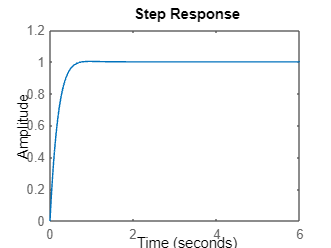

 
%% 3.2

Ts1 = 0.03;
Ts2 = 0.005;

Gcl = (Gr * Gp) / (1 + Gr * Gp);

step(Gcl, u)


G_R = (1/Gp) *(Gr/(1-Gr))

G_R =
 
  0.1507 s^5 + 4.735 s^4 + 54.58 s^3 + 273 s^2 + 500 s
  ----------------------------------------------------
      0.2255 s^4 - 1.306 s^3 - 94.96 s^2 - 593.5 s
 
Continuous-time transfer function.
Model Properties



G_R = minreal(Gr)

G_r =
 
  0.81 s^2 + 13 s + 50
  --------------------
       s^2 + 10 s
 
Continuous-time transfer function.
Model Properties




Grd1 = c2d(G_R, Ts1, 'Tustin') 

Grd1 =
 
  85.78 z^5 - 357 z^4 + 592.4 z^3 - 490 z^2 + 202.1 z - 33.24
  -----------------------------------------------------------
   z^5 - 3.748 z^4 + 2.897 z^3 + 2.512 z^2 - 3.897 z + 1.236
 
Sample time: 0.03 seconds
Discrete-time transfer function.
Model Properties



Grd2 = c2d(G_R, Ts2, 'Tustin') 

Grd2 =
 
  293.9 z^5 - 1424 z^4 + 2760 z^3 - 2675 z^2 + 1296 z - 251.1
  -----------------------------------------------------------
     z^5 - 3.04 z^4 + 2.07 z^3 + 2.011 z^2 - 3.07 z + 1.03
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties



[num2,den2] = tfdata(Grd1);

[num3,den3] = tfdata(Gr);